tic
% Bifurification parameter
Gin = 0:5:900;
nValues = length(Gin);

%Constants for all trials
const = models.constants;
const.tau1 = 7;
const.tau2 = 36;
const.td = 36;

constArray(1:nValues) = const;

% Initial conditions
% Li et al
liState = [13000; % Glucose
         30]; % Insulin
% Sturis et al. and Tolic et al conditions
sturisState = [30; % Ip
               0; % Ii
               14000; % G
               0; % x1
               0; % x2
               0]; % x3

% Simulation time               
time = [0, 10000];

% Vectors for results
% Form: min G, max G, min I, max I
LiResults = zeros(nValues, 4);
SturisResults = zeros(nValues, 4);
tolicResults = zeros(nValues, 4);

% Store Values
parfor i=1:nValues
    % Update Gin value
    constArray(i).Gin = Gin(i);
    
    % Solve Equations
    sol = liSolver(liState, constArray(i), time);
    [t, y] = sturisSolver(sturisState, constArray(i), time);
    [tT, yT] = tolicSolver(sturisState, const, time);
    
    LiResults(i,:) = [min(sol.y(1,end-200:end)), max(sol.y(1,end-200:end))...
                      min(sol.y(2,end-200:end)), max(sol.y(2,end-200:end))];
    SturisResults(i,:) = [min(y(end-150:end,3)), max(y(end-150:end,3))...
                      min(y(end-150:end,1)), max(y(end-150:end,1))];
    TolicResults(i,:) = [min(yT(end-150:end,3)), max(yT(end-150:end,3))...
                         min(yT(end-150:end,1)), max(yT(end-150:end,1))];
end


toc

Elapsed time is 231.271205 seconds.


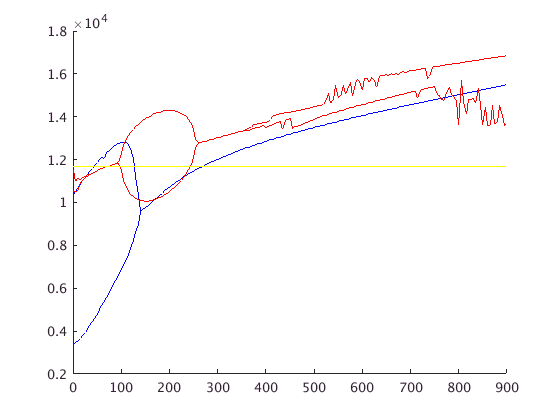

%%
hold on
plot(Gin, LiResults(:,1), 'b')
plot(Gin, LiResults(:,2), 'b')
plot(Gin, SturisResults(:,1), 'r')
plot(Gin, SturisResults(:,2), 'r')
plot(Gin, TolicResults(:,1), 'y')
plot(Gin, TolicResults(:,2), 'y')
hold off